# Interpolacja

Interpolacja polega na wyznaczaniu wartości funkcji danej tabelarycznie pomiędzy znanymi punktami.

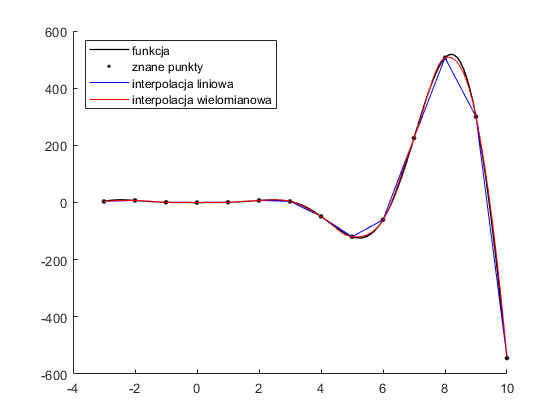

xx = -3:0.1:10;
yy = xx.^3.*sin(xx);


x = -3:10;
y = x.^3.*sin(x);

yp1 = interp1(x,y,xx,"linear"); % interpolacja liniowa
yp2 = interp1(x,y,xx,"cubic"); % interpolacja wielomianowa 

newplot()
hold on
plot(xx,yy,"black","LineWidth",1.0)
scatter(x,y,100,"black",'.')
plot(xx,yp1,"blue","LineWidth",0.5)
plot(xx,yp2,"red","LineWidth",0.5)
legend(["funkcja","znane punkty","interpolacja liniowa","interpolacja wielomianowa"],"Location","best")
hold off

Interpolacja na siatce trójkątów:

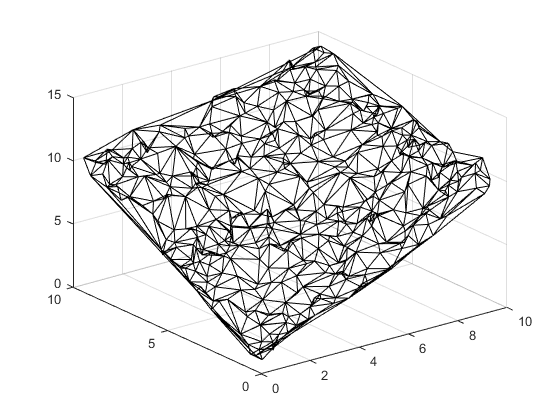

N = 500;
s = [N,1];
x = rand(s)*10;
y = rand(s)*10;
z = sqrt(x.^2+y.^2) + rand(s);


triangulacja = delaunay(x,y);

trimesh(triangulacja,x,y, z,'EdgeColor','black', 'FaceColor','none')

F = scatteredInterpolant(x,y,z)

F =   scatteredInterpolant with properties:

                 Points: [500×2 double]
                 Values: [500×1 double]
                 Method: 'linear'
    ExtrapolationMethod: 'linear'


xp = 0:0.1:10;
yp = 0:0.1:10;
[Xp,Yp] = meshgrid(xp,yp);
F(Xp,Yp)

ans =     1.3514    1.4228    1.4943    1.5658    1.6374    1.7091    1.7808    1.8525    1.9244    1.9962    2.0682    2.1402    2.2122    2.2843    2.3565    2.4287    2.5010    2.5733    2.6457    2.7181    2.7906    2.8632    2.9358    3.0085    3.0812    3.1540    3.2269    3.2998    3.3727    3.4457    3.5188    3.5919    3.6651    3.7384    3.8117    3.8850    3.9585    4.0411    4.1341    4.2271    4.3202    4.4133    4.5065    4.5997    4.6929    4.7862    4.8795    4.9729    5.0663    5.1598
    1.3155    1.3874    1.4595    1.5316    1.6037    1.6759    1.7481    1.8205    1.8928    1.9653    2.0377    2.1103    2.1829    2.2555    2.3282    2.4010    2.4738    2.5467    2.6197    2.6927    2.7657    2.8388    2.9120    2.9852    3.0585    3.1318    3.2052    3.2787    3.3522    3.4257    3.4994    3.5730    3.6468    3.7206    3.7944    3.8683    3.9423    4.0246    4.1188    4.2131    4.3074    4.4018    4.4962    4.5906    4.6851    4.7796    4.8742    4.9688    5.0634   

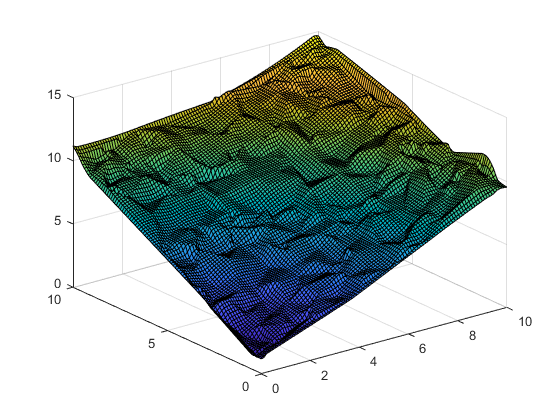

surf(Xp,Yp,F(Xp,Yp))

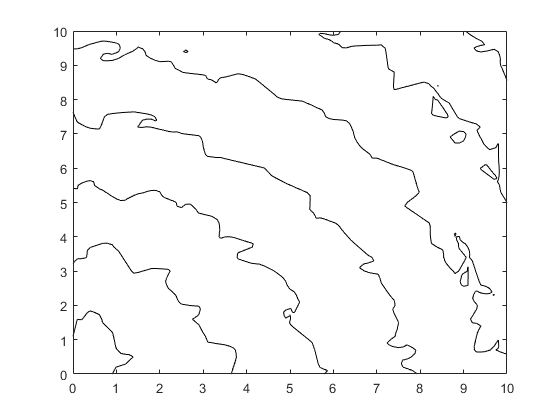

contour(Xp,Yp,F(Xp,Yp),"black")